# Color Differences

Github Link: https://github.com/pratheepkumar1/Principles-of-Color-Science

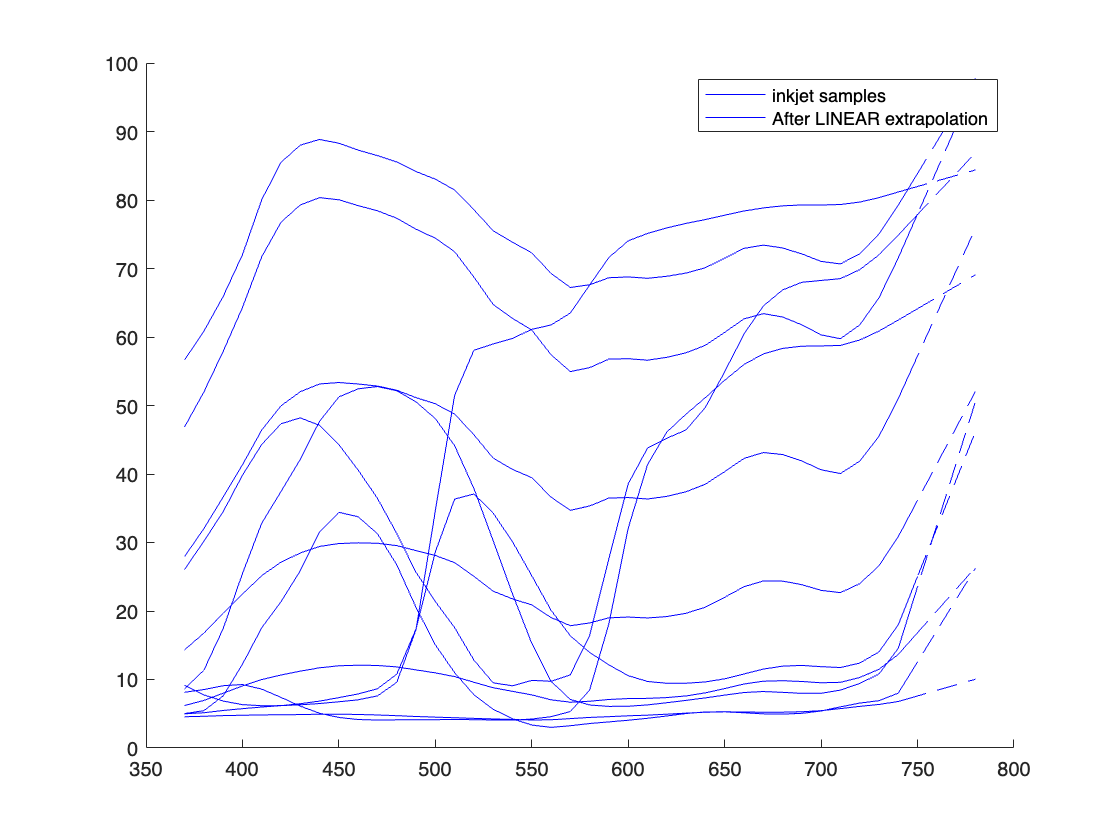

% Reading the Dataset
warning('off','all');
inkjetColorChecker_dataset = readtable("InkjetColorChecker.xlsx");
source_dataset = readtable("Illuminant Data.xlsx");
xyz_std_obs_two_deg_dataset = readtable("StdObsFuncs.xlsx",Sheet="2-degree");
patch_dataset = readtable("MacbethColorChecker.xlsx");


d_lambda = 5;
wavelength_info = 380:5:780;


%Interpolating and extrapolating the dataset (as needed)
xyz_std_obs_two_deg = interp1(xyz_std_obs_two_deg_dataset{:,1},...
    xyz_std_obs_two_deg_dataset{:,2:end},wavelength_info,"linear","extrap");
source_A = interp1(source_dataset{:,1},source_dataset.A,...
    wavelength_info,"linear","extrap");
source_D65 = interp1(source_dataset{:,1},source_dataset.D65,...
    wavelength_info,"linear","extrap");
patch_macbeth_ref = interp1(patch_dataset{2:end,1},patch_dataset{2:end,2:end},...
    wavelength_info,"linear","extrap");
inkjetColorChecker = interp1(inkjetColorChecker_dataset{2:end,1},....
    inkjetColorChecker_dataset{2:end,2:end},wavelength_info,"linear","extrap");

inkjetColorChecker_alt = interp1(inkjetColorChecker_dataset{2:end,1},...
    inkjetColorChecker_dataset{2:end,2:end},wavelength_info,"linear","extrap");



figure(1)
hold on
plot(inkjetColorChecker_dataset{2:end,1},inkjetColorChecker_dataset{2:end,2:end},...
    'Color','blue');
plot(wavelength_info,inkjetColorChecker(:,1:end),'--','Color','blue');
% plot(wavelength_info,inkjetColorChecker_alt(:,1),'--','Color','red');
legend('inkjet samples','After LINEAR extrapolation');
hold off

The provided dataset for inkjet color patches is available from 360nm to 750nm with 10nm difference. Whereas, Macbeth color check dataset is available from 380nm to 780nm with 5nm difference. So, the inkjet color patches (batch) data set is interpolated and extrapolated to match Macbeth patches (standard) wavelength range. For extrapolation of the dataset, there are multiple options to extrapolate such as linear, nearest, cubic. Out of this, linear extrapolation provided better dataset for the missing wavelength in have has a curve below. Above figure graphically shows the difference between before and after extrapolation of inkjet color patches.

% White point value of Source A and Source D65 for 2 degree observer
wp_A_two_deg_source = calcTristimulusSource(xyz_std_obs_two_deg,source_A,d_lambda);
wp_D65_two_deg_source = calcTristimulusSource(xyz_std_obs_two_deg,source_D65,d_lambda);

## Question 1

Compute and make tables of CIELAB values of the inkjet-printed patches from the spectral reflectance data for Illuminants A and D65. 

*Note: Calculation for CIELAB values as written as separate function script file (calXYZtoCIELAB.m)*

% Tristimulus value for all patches in InkjetColorChecker in A and D65 Source ...
% for 2 degree observer
tristimulus_XYZ_A_two_deg_inkjet = calcTristimulus(xyz_std_obs_two_deg,...
    source_A,inkjetColorChecker,d_lambda);
tristimulus_XYZ_D65_two_deg_inkjet = calcTristimulus(xyz_std_obs_two_deg,...
    source_D65,inkjetColorChecker,d_lambda);


%Calculate L_star, a_star, b_star, C_star for all patches in InkjetColorChecker...
% in A and D65 Source 
[L_A_inkjet, a_A_inkjet, b_A_inkjet, C_A_inkjet] = calcXYZtoCIELAB...
    (tristimulus_XYZ_A_two_deg_inkjet,wp_A_two_deg_source);
[L_D65_inkjet, a_D65_inkjet, b_D65_inkjet, C_D65_inkjet] = calcXYZtoCIELAB...
    (tristimulus_XYZ_D65_two_deg_inkjet,wp_D65_two_deg_source);

CIELAB_A_inkjet = [L_A_inkjet; a_A_inkjet; b_A_inkjet; C_A_inkjet];
CIELAB_D65_inkjet = [L_D65_inkjet; a_D65_inkjet; b_D65_inkjet; C_D65_inkjet];


table_CIELAB_A_inkjet = createTableCIELAB(CIELAB_A_inkjet)

table_CIELAB_A_inkjet = 12×4 table
      L          a          b         C   
    ______    _______    _______    ______

     184.6     19.515    -260.28    261.01
    293.21    -164.34     88.317    186.57
    284.03        246     182.65     306.4
    449.83     40.224     345.06     347.4
    316.24     199.83    -99.457    223.22
    269.12    -153.77     -238.1    283.44
     465.2    -10.841    -54.048    55.124
    438.21    -14.023    -70.874    72.248
    377.08     -12.67    -68.652    69.811
    302.22     -11.68     -66.08    67.104
    214.45    -6.0814    -55.158    55.492
    175.41     14.305     -7.415    16.113


table_CIELAB_D65_inkjet = createTableCIELAB(CIELAB_D65_inkjet)

table_CIELAB_D65_inkjet = 12×4 table
      L          a          b         C   
    ______    _______    _______    ______

    199.42      113.6    -241.89    267.24
    306.25    -210.29     132.53    248.57
    252.91     239.47     125.42    270.33
    438.58    -19.734     357.46       358
    300.05     235.72    -140.33    274.32
     296.6    -81.346    -189.97    206.65
    468.71    -1.1817    -49.473    49.487
     442.9    -1.6201    -64.503    64.524
    381.71     -2.536    -61.691    61.743
    306.75    -2.9144    -58.846    58.918
    217.94     1.3599    -49.742    49.761
    174.46     15.286    -9.8599     18.19


## Question 2 (Prerequisite Calculations)

Calculating CIELAB values for Macbeth refpatches

% Tristimulus value for all patches in InkjetColorChecker in A and D65 Source...
% for 2 degree observer
tristimulus_XYZ_A_two_deg_macbeth_ref = calcTristimulus(xyz_std_obs_two_deg,...
    source_A,patch_macbeth_ref,d_lambda);
tristimulus_XYZ_D65_two_deg_macbeth_ref = calcTristimulus(xyz_std_obs_two_deg,...
    source_D65,patch_macbeth_ref,d_lambda);

%Calculate L_star, a_star, b_star, C_star for all patches in InkjetColorChecker...
% in A and D65 Source 
[L_A_macbeth_ref, a_A_macbeth_ref, b_A_macbeth_ref, C_A_macbeth_ref] = ...
    calcXYZtoCIELAB(tristimulus_XYZ_A_two_deg_macbeth_ref,wp_A_two_deg_source);
[L_D65_macbeth_ref, a_D65_macbeth_ref, b_D65_macbeth_ref, C_D65_macbeth_ref] = ...
    calcXYZtoCIELAB(tristimulus_XYZ_D65_two_deg_macbeth_ref,wp_D65_two_deg_source);

CIELAB_A_macbeth_ref = [L_A_macbeth_ref; a_A_macbeth_ref; b_A_macbeth_ref;...
    C_A_macbeth_ref];
CIELAB_D65_macbeth_ref = [L_D65_macbeth_ref; a_D65_macbeth_ref; b_D65_macbeth_ref;...
    C_D65_macbeth_ref];

table_CIELAB_A_macbeth_ref = createTableCIELAB(CIELAB_A_macbeth_ref);
table_CIELAB_D65_macbeth_ref = createTableCIELAB(CIELAB_D65_macbeth_ref);

## Question 2

Calculate and make tables of ΔL*, Δa*, Δb*, ΔC*, ΔH*, ΔE*ab and ΔE*00 color differences *(Please put columns in this order to make grading easier!)* between the 12 corresponding patches on the inkjet-printed ColorChecker (sample set) and the real ColorChecker (reference set). You can calculate ΔE*00 with the provided m-file (it takes Lab arrays in 3xN orientation), but please write you own Matlab code for the other differences. Please make a two tables: one for the D65 data and one for the A data.

*Note: Calculation for color difference values as written as separate function below*


% Delta calculation for A
deltaL_A = deltaL(L_A_inkjet,L_A_macbeth_ref(:,13:24));

deltaa_A = deltaa(a_A_inkjet,a_A_macbeth_ref(:,13:24));

deltab_A = deltab(b_A_inkjet,b_A_macbeth_ref(:,13:24));

deltaC_A = deltaC(C_A_inkjet,C_A_macbeth_ref(:,13:24));

deltah_A = deltah(CIELAB_A_inkjet,CIELAB_A_macbeth_ref(:,13:24));

deltaH_A = deltaH(C_A_inkjet,C_A_macbeth_ref(:,13:24),deltah_A);

deltaEab_A = deltaEab(deltaL_A,deltaC_A,deltaH_A);

deltaE00_A = deltaE00(CIELAB_A_inkjet,CIELAB_A_macbeth_ref(:,13:24));

CP1 =   261.0060  186.5683  306.3972  347.4010  223.2168  283.4379   55.3198   72.2963   69.8627   67.1634   55.5501   22.5439


CP2 =    54.1254   45.2637   68.1089   77.8904   48.3301   48.2377    0.5139    0.1342    0.1806    0.1516    0.7328    1.0836



color_diff_A = [deltaL_A; deltaa_A; deltab_A; deltaC_A; deltaH_A; deltaEab_A; deltaE00_A];



% Delta calculation for D65

deltaL_D65 = deltaL(L_D65_inkjet,L_D65_macbeth_ref(:,13:24));

deltaa_D65 = deltaa(a_D65_inkjet,a_D65_macbeth_ref(:,13:24));

deltab_D65 = deltab(b_D65_inkjet,b_D65_macbeth_ref(:,13:24));

deltaC_D65 = deltaC(C_D65_inkjet,C_D65_macbeth_ref(:,13:24));

deltah_D65 = deltah(CIELAB_D65_inkjet,CIELAB_D65_macbeth_ref(:,13:24));

deltaH_D65 = deltaH(C_D65_inkjet,C_D65_macbeth_ref(:,13:24),deltah_D65);

deltaEab_D65 = deltaEab(deltaL_D65,deltaC_D65,deltaH_D65);

deltaE00_D65 = deltaE00(CIELAB_D65_inkjet,CIELAB_D65_macbeth_ref(:,13:24));

CP1 =   267.2406  248.5668  270.3293  358.0019  274.3239  206.6549   49.4911   64.5253   61.7486   58.9278   49.7665   24.7154


CP2 =    56.5057   54.2836   58.7252   79.4899   51.6621   35.8680    0.8785    0.1982    0.0866    0.1054    0.5222    0.9483



color_diff_D65 = [deltaL_D65; deltaa_D65; deltab_D65; deltaC_D65;...
    deltaH_D65; deltaEab_D65; deltaE00_D65];


table_color_diff_A = createTableColorDiff(color_diff_A)

table_color_diff_A = 12×7 table
      ΔL        Δa         Δb         ΔC        ΔH        ΔEab      ΔE00 
    ______    _______    _______    ______    _______    ______    ______

     157.5     16.969    -206.21    206.88      3.301    260.03    89.233
    239.71    -128.15     61.127     141.3     13.885    278.61    87.249
    236.18     189.27     144.97    238.29     7.5525    335.59    89.926
    365.41     30.418     267.79    269.51     1.6756    454.06    89.566
    260.68     151.74    -94.717    174.89    -37.555    316.15     89.79
    222.22    -121.27    -202.45     235.2      19.37    324.16    89.313
    369.73    -10.883     -54.56     54.61     10.624    373.89    86.792
    357.24    -14.077    -70.996    72.114     6.1822     364.5


table_color_diff_D65 = createTableColorDiff(color_diff_D65)

table_color_diff_D65 = 12×7 table
      ΔL         Δa         Δb         ΔC        ΔH        ΔEab      ΔE00 
    ______    ________    _______    ______    _______    ______    ______

    169.43      88.989    -191.03    210.73    -1.4207     270.4    89.872
     250.6      -168.6     97.757    194.28      15.43    317.47    88.228
    211.97      186.63     99.813     211.6     3.9363    299.54    90.039
    356.94     -18.158     277.98    278.51     5.9594    452.78    89.765
    249.05      186.29    -125.29    222.66    -28.691     335.3    90.703
    244.92     -56.619    -163.99    170.79     30.494    300.14    89.718
    373.24    -0.82465    -50.251    48.631     12.683    376.61    86.869
    361.94     -1.7618    -64.637    64.329     6.53

## Question 3

Discuss your results, including what you observe between the two ΔE metrics and what you lose by using a ΔE value as opposed to its components (ΔL*, Δa*, Δb*, ΔC*, ΔH*).

- E00 results are normalized and optimized better than E65 for estimating the color difference which will be good for comparison with visual color difference. Also, E00 has significantly lower standard deviation (S.D = 1.4) in color difference for the given batch when compared to Eab (S.D: 78.25). This difference for E00 is acheived by normalizing Eab with the weightness color difference parameter with recirpocal weight and position function.

- For chromatic patches, the color with higher chromatic difference difference (Path 16), value has greater difference in value between two ΔE metrics for both the illuminant A and D65. Chromatic difference have a bigger magnitude in color euclidean difference calculation. That’s why chromatic changes are very noticeable while comparing chromatic color pairs.

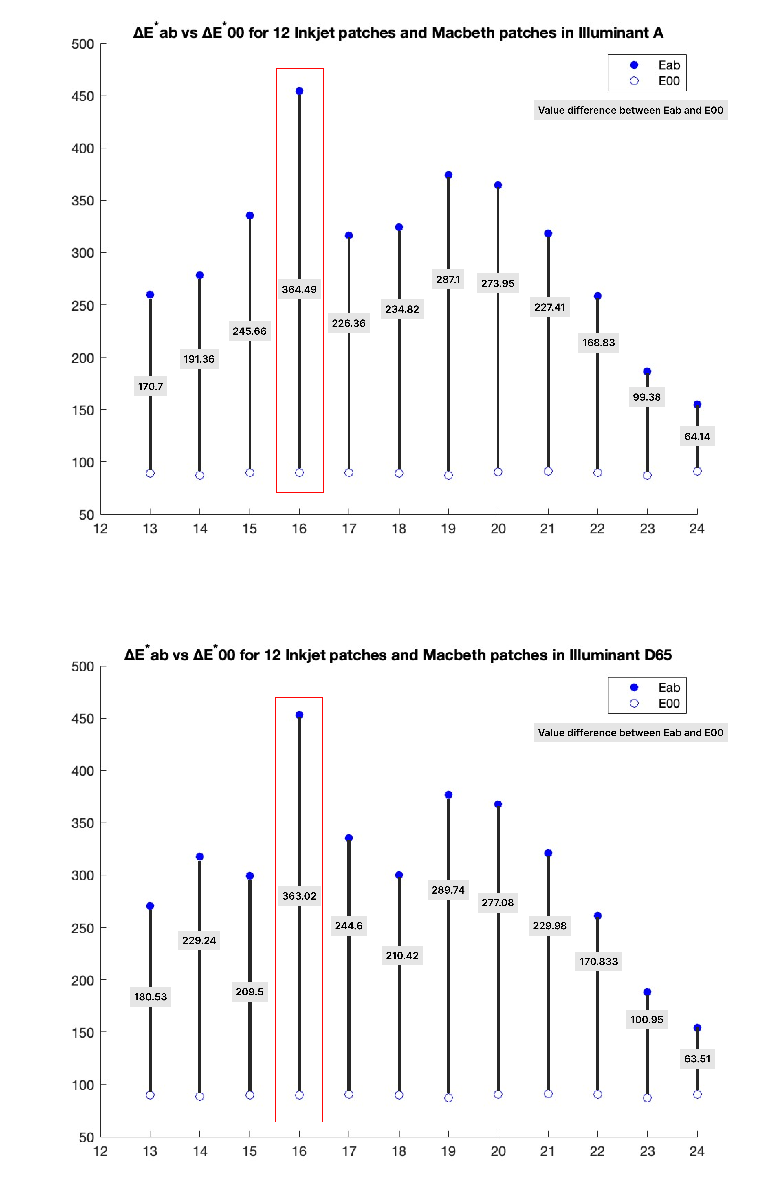

- Whereas for achromatic patches, colors with higher lightness difference (Path 19) impact the difference in value between two ΔE metrics for both the illuminant A and D65. I doubt that this gradual decreases in difference between two ΔE metrics for decreasing lightness for achromatic patches might correlate with the compressive response.

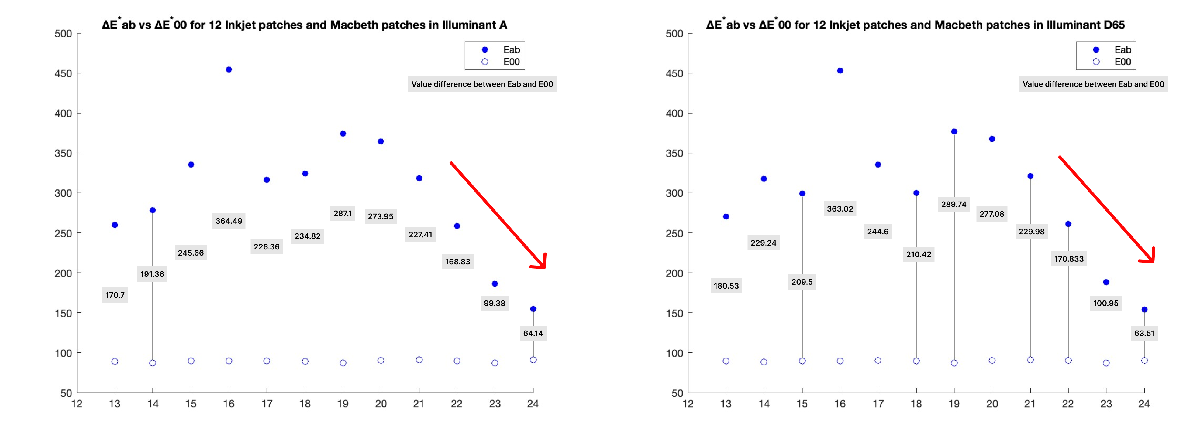

- We will loose the quantification of visual color specifications as such lightness, chroma, hue while using ΔE value.  Also, while plotting the  Δa* vs  Δb*, ΔC* vs ΔL*, ΔH* we can have a colored background to specify the standard and batch colors position with respect to it’s coordinates for that specification. But plotting ΔE don’t give such information, rather we can use it to compare how much difference it has between visual difference. So to summarize, it is a mathematical representation of sensation difference where as other components are mathematical representation color specification differences

## Question 4

Under which illuminant is the inkjet print a better match to the real ColorChecker?

- In general, inkjet add more chroma to achromatic color patches (shown in below figures). This chromatic addition tends to move towards bluish color for achromatic patches. If we try to analyse the difference based on Euclidean distance, the one illuminant have outperformed the other in the certains patches. That is, some patches has less euclidean distance in illuminant A whereas some patch in illuminant A has more Eucledian difference than illuminant D65. 

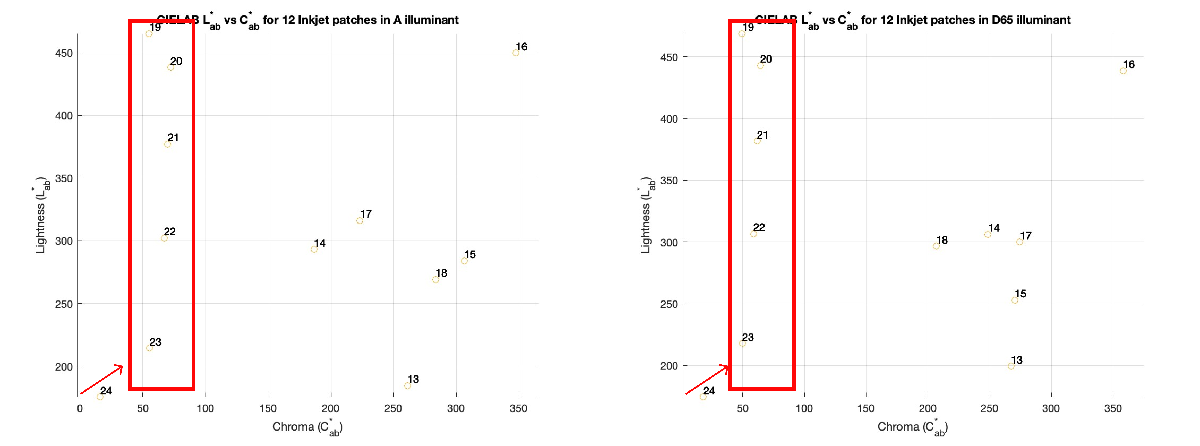

Inkjet Patch

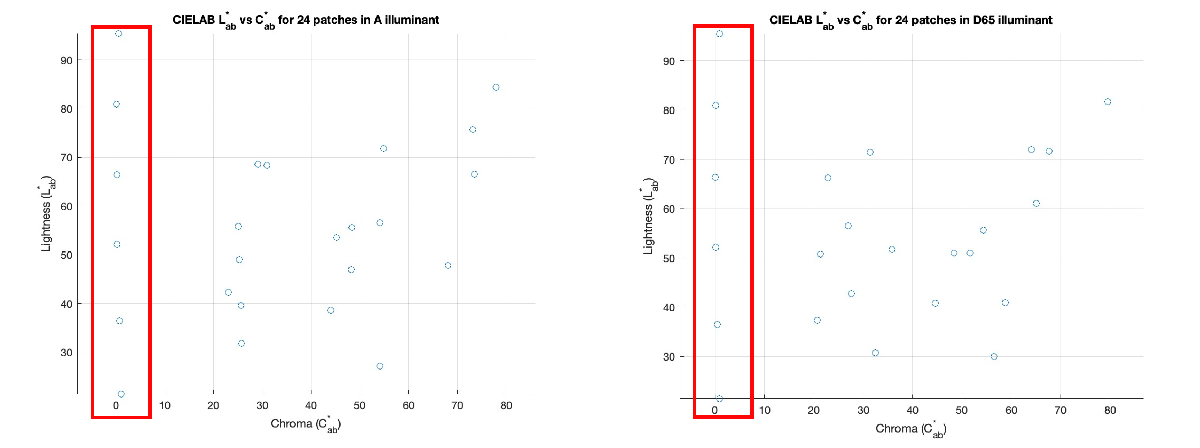

Macbeth Patch

- Instead of choosing a better illuminant overall for all patches, I decided to choose a better illuminant each each color and it's properties. For green and blue patches (Patch 12 and 13) , inkjet patches under illuminant A matches better with the standard batch. But if the chroma of those colors increases (especially patch 18 - blue), illuminant D65 is better. 

- Whereas, for achromatic batches, illuminant A is better because it counterbalances the additional blue color effect produced by the inkjet. This counterbalancing happens because of the yellowish nature of illuminant A (Incandescent Light)

## Functions

%Function to create table and assign CIELAB values

function a2t = createTableCIELAB(values)
    a2t = array2table(values');
    a2t.Properties.VariableNames(1:4) = {'L','a','b','C'};
end

function a2t = createTableColorDiff(values)
    a2t = array2table(values');
    a2t.Properties.VariableNames(1:7) = {'ΔL','Δa','Δb','ΔC','ΔH','ΔEab','ΔE00'};
end

%Function to calculate Delta L
function DL = deltaL(L_bat,L_std)
    DL = L_bat - L_std;
end


%Function to calculate Delta a
function Da = deltaa(a_bat,a_std)
    Da = a_bat - a_std;
end


%Function to calculate Delta b
function Db = deltab(b_bat,b_std)
    Db = b_bat - b_std;
end

%Function to calculate Delta C*
function DC = deltaC(C_bat,C_std)
    DC = C_bat - C_std;
end


%Function to calculate Delta h
function Dh = deltah(bat,std)
    Dh = hueAngle(bat(2,:),bat(3,:)) - hueAngle(std(2,:),std(3,:));
end


%Function to calculate hue angle
function h = hueAngle(a,b)
    h = atan2Deg(b,a);
end


%Function to calculate Delta H
function DH = deltaH(C_bat,C_std,deltah)
    DH = 2*(C_bat.*C_std).^(1/2).*sinDeg(deltah./2);
end


%Function to calculate Delta Eab
function e = deltaEab(deltaL,deltaa,deltab)
    e = sqrt(deltaL.^2 + deltaa.^2 + deltab.^2);
end


function out = atan2Deg(inY,inX)
    out = atan2(inY,inX).*180./pi;
    out = out+(out<0).*360;
end


function out = sinDeg(in)
    out = sin(in.*pi./180);
end